# Parcialito de MATLAB

# 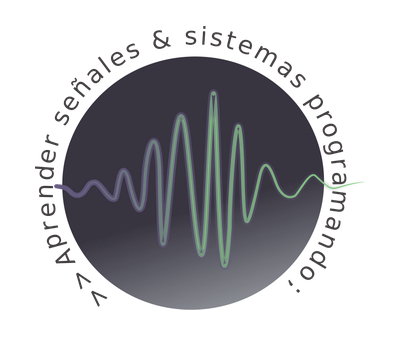

## Consigna

Desarrollar un script que permita generar señales discretas básicas, realizar operaciones entre ellas, visualizar, cargar y almacenar resultados. Ademas realizar el diagrama de flujo simplificado ([Herramienta online](https://www.draw.io)) del script diseñado.

IDEAS PARA PROXIMO PARCIAL

DESCOMPONER EN PARES E IMPARES

OTROS OPERADORES(NORMALIZAR, VENTANAS)

DESCRIPTORES (RMS, VALOR MEDIO)

## Desarrollo

Una función constructora que llama a las funciones locales con **handles **(ayuda: clase_03_b). El script debe contar con 3 hilos de procesamiento:

**Hilo 1**

- `main.m`: función principal que llama las funciones del hilo 2 e hilo 3. Ejemplo de aplicacion de los hilos 2 y 3:

sig = dicSignal;
[y,n] = sig.impulso(0,-10,10); % Donde (posición del cero, inicio de la señal, final de la señal)
salida = viewSignal;
salida.graficar(y, n,'impulso');
salida.guardarM(y, n,'resultado');

**Hilo 2**

- `discSignal`: función que genera **handles** de señales discretas (secuencias) (ayuda: clase02_a). Las funciones locales, como minimo son:

                - `@impulso`: función local que devuelve la secuencia de un **impulso unitario**:


$$\delta \left\lbrack n \right\rbrack =\left\lbrace \begin{array}{c}
1 & n=0 \\
0 & n\ne 0
\end{array}\right.$$


                - `@escalon`: función local que devuelve la secuencia de un **escalón unitario**:


$$U\left\lbrack n \right\rbrack =\left\lbrace \begin{array}{c}
1 & n\ge 0 \\
0 & n<0 
\end{array}\right.$$


                - `@pulso`: función local que devuelve la secuencia de un **pulso unitario **de un ancho definido:


$$P \left\lbrack n-n_0 \right\rbrack =\left\lbrace \begin{array}{c}
1 &  \vert n-n_0 \vert \le w \\
0 & \text{ en otro caso}
\end{array}\right. \text{     , con w el ancho del pulso}$$


                - `@triangular:` función local que describe la secuencia **triangular:**


$$T \left\lbrack n \right\rbrack =\left\lbrace \begin{array}{c}
1-\vert n \vert & \vert n \vert \le 1 \\
0 & \text{ en otro caso}
\end{array}\right.$$


                - `@rampa`: función local que describe la secuencia **rampa**:


$$r[n]=\begin{cases} n, \text{para } n \ge 0  \\  0, \text{para  } n <0 \end{cases}$$


                - `@exponencial`: función local que describe la secuencia **exponencial**:


$$x\left\lbrack n\right\rbrack =a^n ,\text{ }\forall n;a\text{ }\in \Re$$


                - `@aleatorio`: función local que describe una secuencia valores aleatorios con distribucion gaussiana (ayuda: `help random`)

            Todas las funciones locales anteriores (ej. @impulso) tienen que tener como **minimo 2** **argumentos de entrada (hay funciones que tal vez no sean suficiente)**:

                - posición del cero (ej. `n0`).

                - inicio de la señal (ej. `n1`).

                - final de la señal (ej. `n2`).

            Todas las funciones locales anteriores (ej. @impulso) tienen que tener como **minimo 2** **argumentos de salida (hay funciones que tal vez no sean suficiente)**:

                - vector de amplitudes (ej. `y`).

                - vector de posiciones (ej. `n`).

            Se puede utilizar funciones que controlen los argumentos para modificar la cantidad (ej. `varargin, nargin, varargout, nargout`).

- operSignal: función que genera handles para operar con las señales (Ayuda: clase_02_a):

                - @trasladarTemporal: 

                - @trasladarAmplitud:

                - @inversionTemporal:

                - @inversionAmplitud:

                - @comprimirExpandirTemporal:

                - @modularAmplitud:

                - @sumarSignals:

                - @multiplicarSignals:

                - @convolucionarSignals:

**Hilo 3**

- viewSignal: función que genera handles para el front-end:

                - @graficar: función local que hace "stem" en función de los argumentos de entrada (Ayuda: clase_02_b).

                - @guardarM: función local que almacena las variables del workspace, en un archivo .m.

                - @guardarDat: función local que almacena  las variables del workspace, en un archivo .m (Ayuda: save -ascii y.dat resultado).

                - @cargarM: función local que carga un archivo .m.

                - @cargarDat: función local que carga un archivo .dat.

## Condiciones de entrega

- Debe entregar los 4 archivos (.m) en una carpeta con el nombre del autor.

- Todas las funciones deben tener docstring y deben respetar los nombre (de las funciones locales) que se mencionan en este documento.

- Los comentarios no deben ser usados en exceso y solo deben aclarar acciones ambiguas.

- El código debe estar indentado.

- Usar estructura de control de errores (`Try , catch`).

- No usar variables globales.

- Las secuencias y las operaciones entre ellas, debe realizarce con código propio y no utilizando funciones preexistentes (a menos que se describa lo contrario).